% """  Fixed Parameters   """ %
s = tf('s');
g = 9.80665;

% """  Drone Transfer   """ %
G = g / s^2; % Drone - Transfer function

% """  Parameters  """ %
OS = 22; % Overshoot (%)
T_s = 18; % Setting time (s)

zeta = - log(OS / 100) / sqrt(pi^2 + log(OS / 100)^2); % Damping ratio
omega_n = 4 / (zeta * T_s); % Natrual frequency

pole_d_plus  = - zeta * omega_n + omega_n * sqrt(zeta^2 - 1) % Desired positive pole

pole_d_plus = -0.2222 + 0.4611i

G_at_pole = evalfr(G,pole_d_plus) % G(pole_d_plus) - Corelation between the desired poles and current poles

G_at_pole = -23.3209 +29.2813i

phi = pi - atan2(imag(G_at_pole),real(G_at_pole)); % Zero angle to G at desired pole (rad)

z_c = real(pole_d_plus) + imag(pole_d_plus) / tan(phi); % a = b / tan(angle)

K = 1/(abs((pole_d_plus + z_c)*G_at_pole)); % Derivitive gain
D = K * (s + z_c)

D =
 
  0.05714 s + 0.008286
 
Continuous-time transfer function.
Model Properties


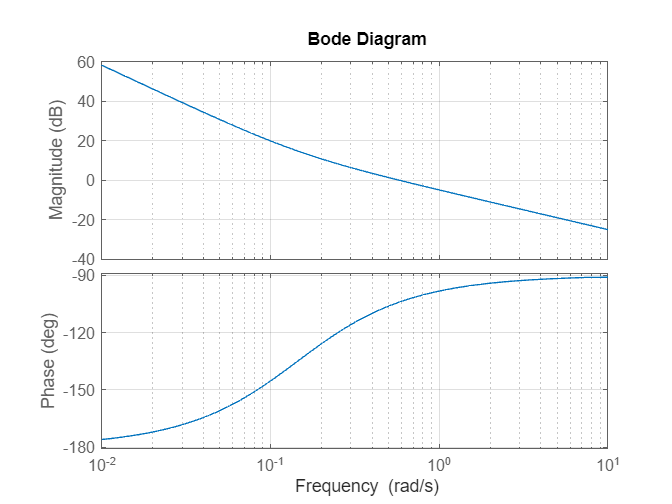



% """  System   """ %
OL = G * D;

% Bode plot
bode(OL)
grid on


%Plot step respons
CL = feedback(OL,1);
%t = linspace(0, 10, 1000);
t = linspace(0,10,10000)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


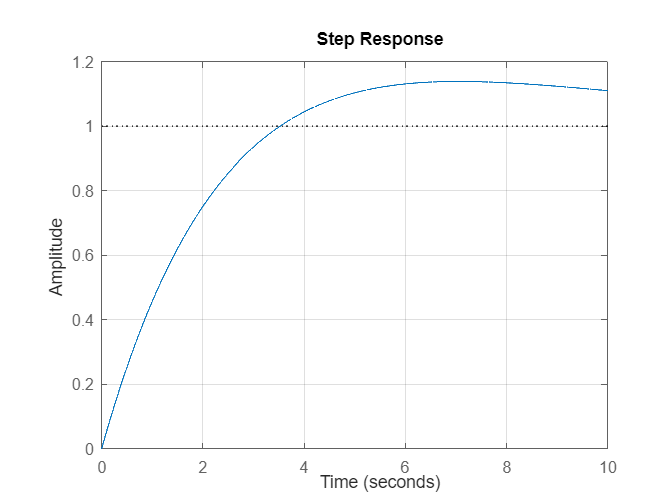

step(CL,t);
grid on;

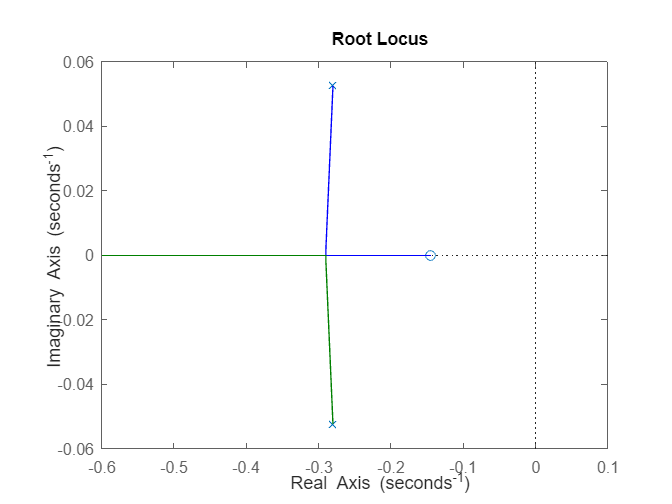


rlocus(CL)


stepinfo(CL)

ans = struct with fields:
         RiseTime: 2.5813
    TransientTime: 18.8274
     SettlingTime: 18.8274
      SettlingMin: 0.9044
      SettlingMax: 1.1385
        Overshoot: 13.8466
       Undershoot: 0
             Peak: 1.1385
         PeakTime: 7.0675



%Ideal system
ideal_sys = tf(omega_n^2, [1, 2*zeta*omega_n, omega_n^2]);
disp('Ideal system: ');

Ideal system: 


stepinfo(ideal_sys)

ans = struct with fields:
         RiseTime: 2.9725
    TransientTime: 16.3714
     SettlingTime: 16.3714
      SettlingMin: 0.9060
      SettlingMax: 1.2200
        Overshoot: 21.9982
       Undershoot: 0
             Peak: 1.2200
         PeakTime: 6.8387